# Práctica 2. Filtros FIR e IIR

#### **Ejercicio 3.**

El archivo mel1.wav contiene una melodía, y el archivo mel1_noise.wav contiene la misma melodía, pero con un ruido añadido. 

**a)** Carga y oye ambas señales.

close all
clear all
load('datos_sonidos.mat')

Representa las señales en el dominio de la frecuencia.

n=length(data_mel);
frec=linspace(0,fs/2,n/2+1);

*El teorema de muestreo de Nyquist establece que para evitar el aliasing y poder recuperar correctamente la información de la señal, la frecuencia de muestreo debe ser al menos el doble de la frecuencia más alta presente en la señal. Por lo tanto, si tu frecuencia de muestreo es fs, la frecuencia más alta que puedes representar sin aliasing es fs/2. Cuando aplicas la FFT a una señal, obtienes un conjunto de frecuencias equiespaciadas en el rango de 0 a fs, y la componente en fs/2 representa la frecuencia máxima que puedes analizar correctamente.*

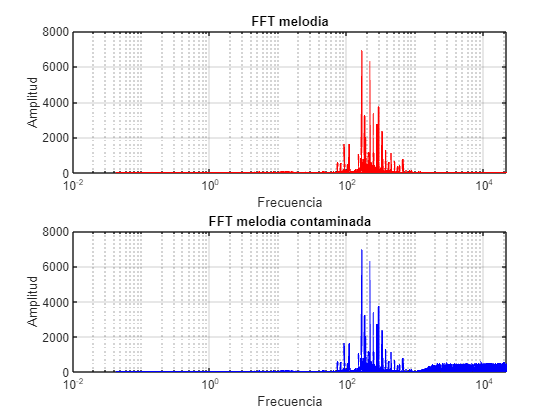

fft_mel=abs(fft(data_mel));
fft_mel=fft_mel(1:length(frec));%Nos quedamos solo con los datos de frecuencia positivos 
fft_noise=abs(fft(data_noise));
fft_noise=fft_noise(1:length(frec));

figure(1)
subplot(2,1,1);
semilogx(frec,fft_mel,'r','LineWidth', 1.5);
ylabel('Amplitud')
xlabel('Frecuencia')
title('FFT melodia');
grid;
subplot(2,1,2)
semilogx(frec,fft_noise,'b','LineWidth', 1.5);
ylabel('Amplitud')
xlabel('Frecuencia')
title('FFT melodia contaminada');
grid;

*Como podemos ver tenemos ruido a partir de los 1000 Hz por lo tanto usaremos un filtro pasa bajo que atenue frecuencias superiores*

** b)** Diseña un filtro FIR con ventana apropiado para eliminar el ruido de la segunda señal, y representa su respuesta en frecuencia.

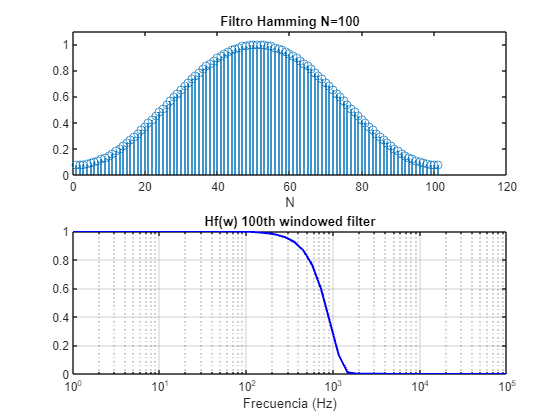

N=100;
fc=800;%%En Hz valor elegido en función de la grafica
fc=2*fc/fs;%frecuencia de corte normalizada a la mitad de la de muestreo por la funcion fir1
hw=hamming(N+1);
num_hamm=fir1(N,fc,'low',hw);
den_hamm=1;
f=logspace(0,5);
G_hamm=freqz(num_hamm,den_hamm,f,fs);
figure(2)
subplot(2,1,1)
stem(hw)
title('Filtro Hamming N=100')
xlabel("N")
ylim([0 1.1]);
subplot(2,1,2)
semilogx(f,abs(G_hamm),'b','LineWidth',1.5); %Representación usando eje x logarítimico
grid;
title('Hf(w) 100th windowed filter')
xlabel('Frecuencia (Hz)')

** c) **Filtra la señal con ruido y compara el resultado con la señal original sin ruido y con la señal con ruido. Para ello, oye la señal filtrada y represéntala en el dominio de la frecuencia. Analiza todas las gráficas.

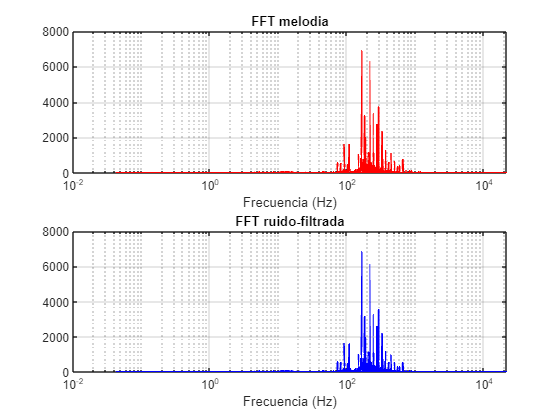

%%Uso del filtro 
noise_filt = filter(num_hamm, den_hamm, data_noise);
noise_fft=abs(fft(noise_filt));
noise_fft=noise_fft(1:length(frec));

figure(3)
subplot(2,1,1)
semilogx(frec,fft_mel,'r','LineWidth',1.5)
title('FFT melodia')
xlabel('Frecuencia (Hz)')
grid;
subplot(2,1,2)
semilogx(frec,noise_fft,'b','LineWidth',1.5)
title('FFT ruido-filtrada')
xlabel('Frecuencia (Hz)')
grid;

sound(mel_filt,fs);

Unrecognized function or variable 'mel_filt'.

pause(length(data_mel)/fs);
sound(noise_filt,fs);
